# The Navier-Stokes equations in vorticity-streamline formulation

## 1. Case description

We want to solve the Navier-Stokes equations for an incompressible fluid on a 2D rectangular domain using the vorticity-streamline function formulation. Using a Cartesian reference, the dimensionless Navier-Stokes equations in vorticity-stramline formulation read as:


$$\frac{\partial \omega }{\partial t}+u\frac{\partial \omega }{\partial x}+v\frac{\partial \omega }{\partial y}=\frac{1}{\mathrm{Re}}\left(\frac{\partial^2 \omega }{\partial x^2 }+\frac{\partial^2 \omega }{\partial y^2 }\right)$$



$$\frac{\partial^2 \psi }{\partial x^2 }+\frac{\partial^2 \psi }{\partial y^2 }=-\omega$$


In the equations above, $\omega$ is the vorticity:


$$\omega =\frac{\partial v}{\partial x}-\frac{\partial u}{\partial y}$$


while $\psi$ is the streamline function, defined as:


$$\begin{array}{l}
u=\frac{\partial \psi }{\partial y}\\
v=-\frac{\partial \psi }{\partial x}
\end{array}$$


The first equations is an advection-diffusion equation for vorticity, while the second equation is a Poisson equation for the streamline function.

We want to solve advection-diffusion equation for vorticity above using the forward Euler method for advancing in time and the centered discretization scheme (2nd order) for discretizing the advective and diffusive terms:


$$\begin{array}{l}
\omega_{i,j}^{n+1} =\omega_{i,j}^{n+1} +\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp -\Delta t\frac{\psi_{i,j+1}^n -\psi_{i,j-1}^n }{2h}\frac{\omega_{i+1,j}^n -\omega_{i-1,j}^n }{2h}+\Delta t\frac{\psi_{i+1,j}^n -\psi_{i-1,j}^n }{2h}\frac{\omega_{i,j+1}^n -\omega_{i,j-1}^n }{2h}+\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp +\Delta t\frac{1}{\mathrm{Re}}\frac{\omega_{i+1,j}^n +\omega_{i-1,j}^n +\omega_{i,j+1}^n +\omega_{i,j-1}^n -4\omega_{i,j}^n }{h^2 }
\end{array}$$


The Poisson equation will be solved using the Successive Over-Relaxation (SOR) method and again centered, 2nd order discretization of spatial derivatives:


$$\frac{\psi_{i+1,j}^n +\psi_{i-1,j}^n +\psi_{i,j+1}^n +\psi_{i,j-1}^n -4\psi_{i,j}^n }{h^2 }=-\omega_{i,j}^n$$


### The lid-driven cavity problem

The lid-driven cavity problem has long been used a test or validation case for new codes or new solution methods. The problem geometry is simple and two-dimensional, and the boundary conditions are also simple. In the standard case, the fluid contained in a square domain with Dirichlet boundary conditions on all sides, with three stationary sides and one moving side (with velocity tangent to the side), according to the picture below:

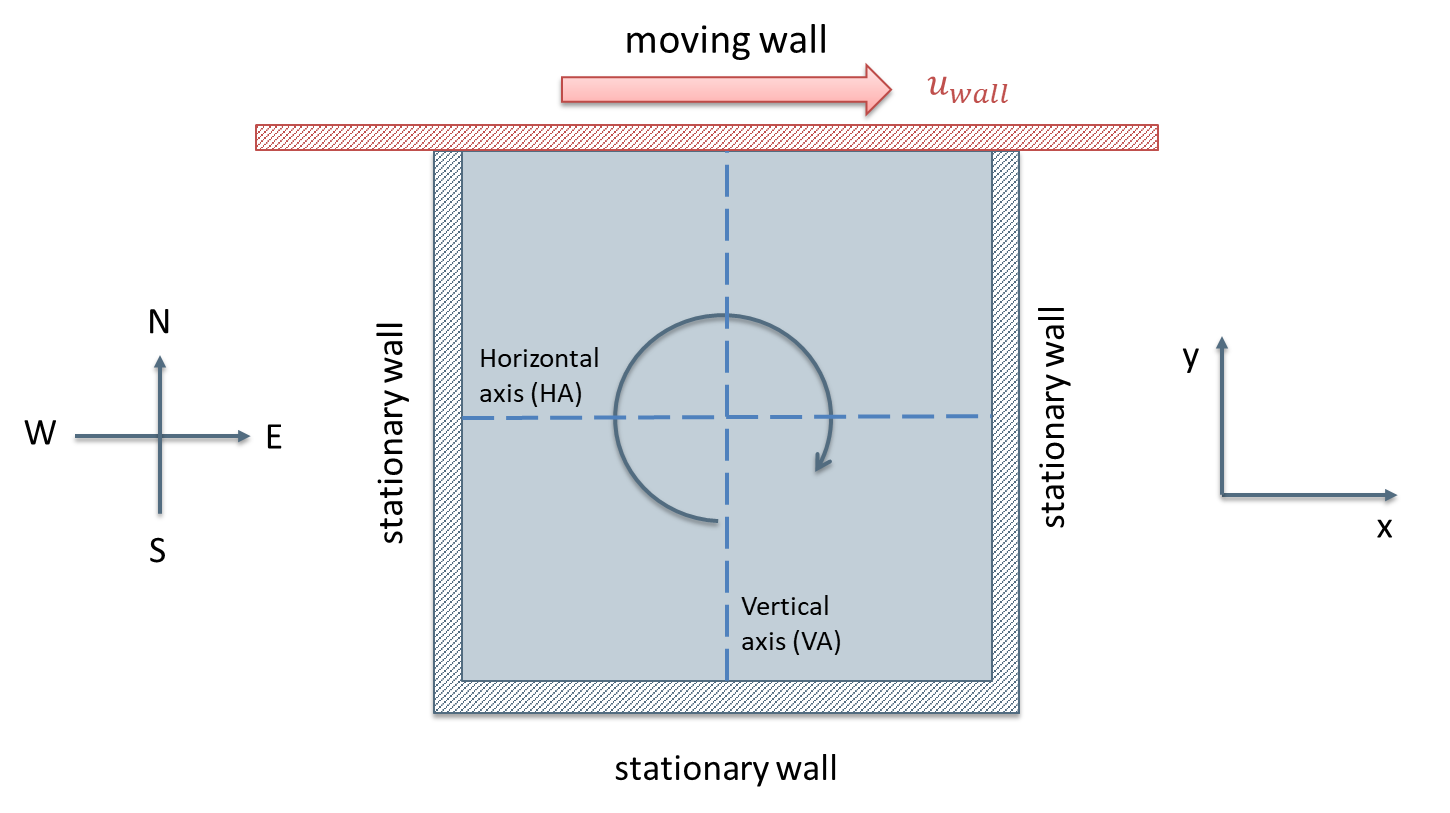

The boundary conditions are reported in the picture below:

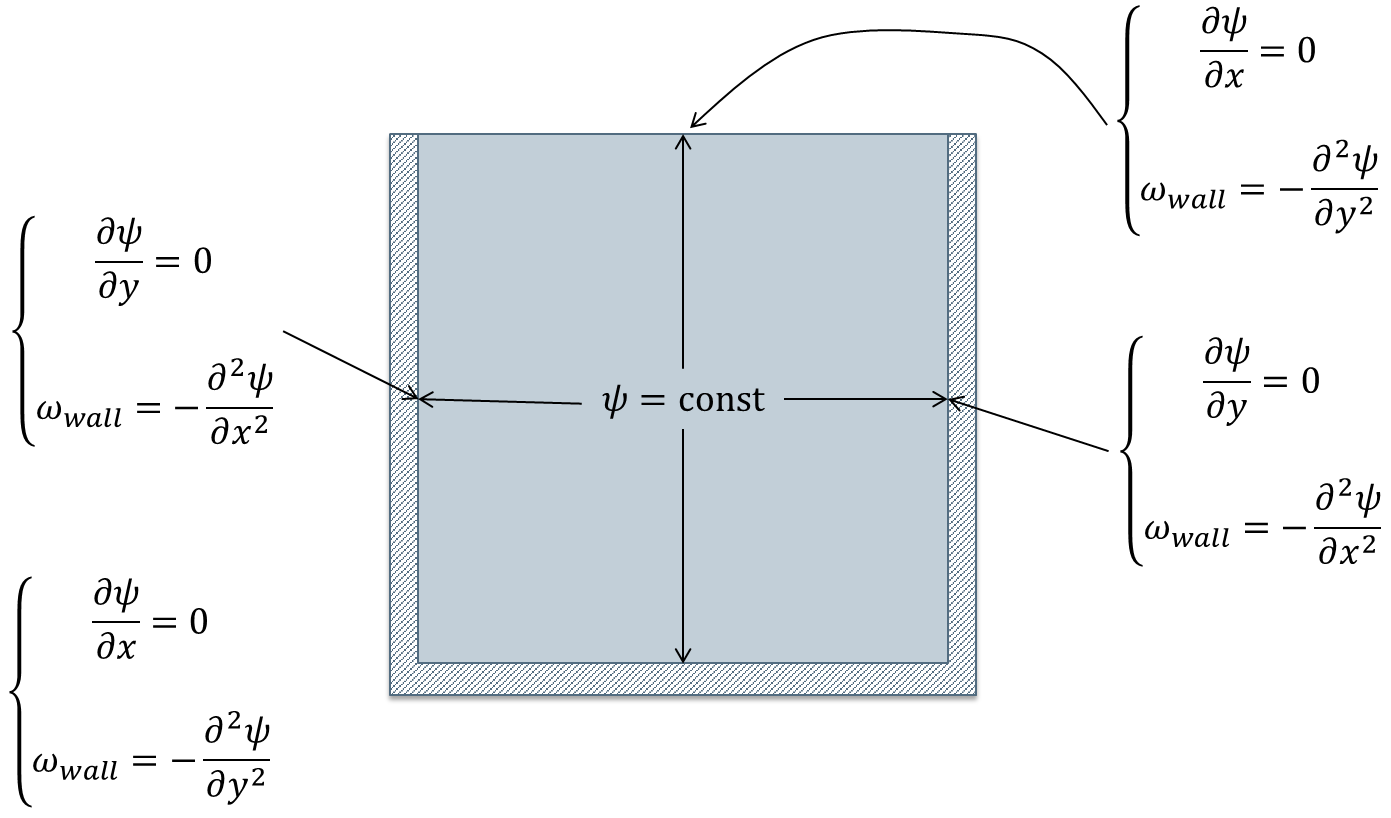

They simply requires that the streamline function is constant along the walls. Since the streamline function always appers in the equations as a spatial derivative, its absolute value is not relevant. Thus, at the end, we can simply say that the boundary conditions for $\psi$ are simply:


$$\psi =0$$


For the vorticity a Dirichlet boundary condition must be accounted for. However, the second derivative of streamline function cannot be calculated along the boundaries using the centered discretization formula. It can be demonstrated that using a Taylor's expansion, the boundary conditions become:


$$\omega_{\mathrm{wall}}^{\mathrm{north}} =-\frac{2}{h}u_{\mathrm{north}} +\frac{2}{h^2 }\left(\psi_{i,N} {-\psi }_{i,N-1} \right)$$



$$\omega_{\mathrm{wall}}^{\mathrm{south}} =\frac{\psi_{i,1} {-\psi }_{i,2} }{h^2 }$$



$$\omega_{\mathrm{wall}}^{\mathrm{west}} =\frac{\psi_{1,j} {-\psi }_{2,j} }{h^2 }$$



$$\omega_{\mathrm{wall}}^{\mathrm{east}} =\frac{\psi_{N,j} {-\psi }_{N-1,j} }{h^2 }$$


Similar simulations have also been done at various aspect ratios, and it can also be done with the lid replaced with a moving fluid. This problem is a somewhat different situation, and is usually referred to as the shear-driven cavity. You may see the two names (lid-driven and shear-driven) used interchangeably in spite of the fact that they are distinct (and different) problems.

This problem has been solved as both a laminar flow and a turbulent flow, and many different numerical techniques have been used to compute these solutions. Since this case has been solved many times, there is a great deal of data to compare with. A good set of data for comparison is the data of Ghia, Ghia, and Shin (1982), since it includes tabular results for various of Reynolds numbers. 

This problem is a nice one for testing for several reasons. First, as mentioned above, there is a great deal of literature to compare with. Second, the (laminar) solution is steady. Third, the boundary conditions are simple and compatible with most numerical approaches. Note that this is not necessarily the case for finite element methods, in which difficulties may arise at the corner intersections of the moving wall and the stationary wall.

### The algorithm

After imposing the initial conditions, we can advance in time according to the strategy summarized in the sollowing picture. At each time step we solve the Poisson equation to update the streamline function. Then, we found the vorticity along the boundaries e we can update the source term in the vorticity equation. Thanks to the forward Euler method, we update the vortiity in the computational domain and we move to the next time step.

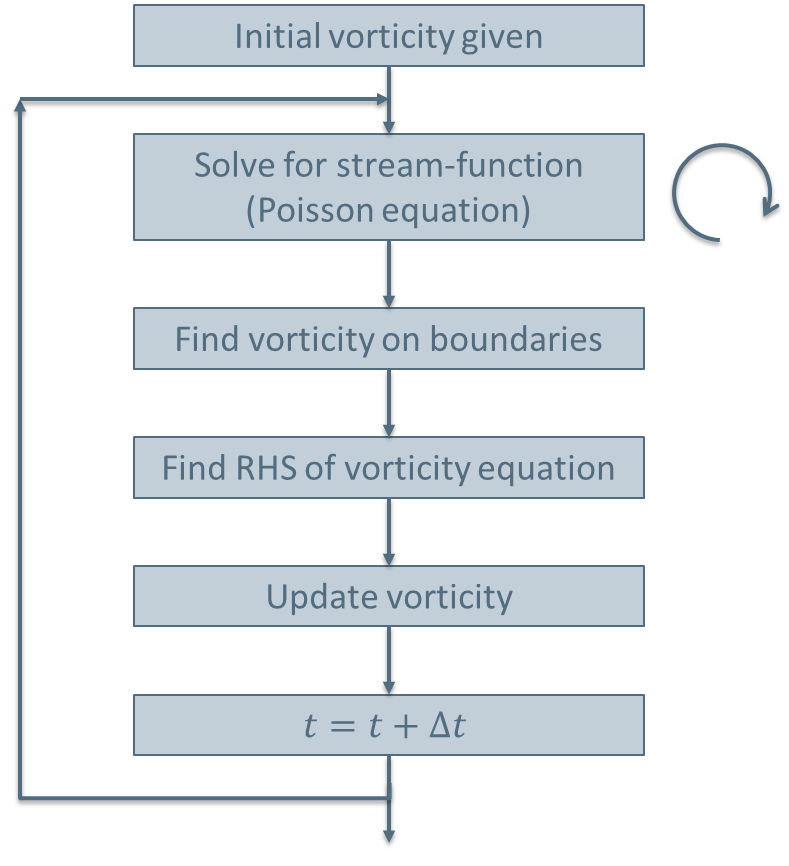

#### References

**Ghia, Ghia, and Shin (1982)**, "High-Re solutions for incompressible flow using the Navier-Stokes equations and a multigrid method", Journal of Computational Physics, Vol. 48, pp. 387-411.

## 2. Implementation

### a. Numerical setup

We start defining the relevant data, i.e.the number of grid points along the two directions (for simplicity we assume the same number), the Reynolds number and the total time of simulation:

nx=25;                  % number of grid points along x
ny=nx;                  % number of grid points along y
Re=100;                 % Reynolds number [-]
tau=20;                 % total time of simulation [-]

Even if not strictly needed for the simulation, we define additional data which are necessary if we want to come back from the dimensionless variables to the real variables (i.e. real distances and velocities):

% Data for reconstructing the velocity field
L=1;                    % length [m]
nu=1e-3;                % kinematic viscosity [m2/s] 
Uwall=nu*Re/L;          % wall velocity [m/s]

We then define the relavant parameters for solving the Poisson equation:

% Parameters for SOR
max_iterations=10000;   % maximum number of iterations
beta=1.9;               % SOR coefficient
max_error=0.0001;      % error for convergence

We pre-process the input data. In particular, we calculate the size step and the time step according to the stability constraints:

% Grid step
h=1/(nx-1);                         % grid step along [-]

% Time step
sigma = 0.5;                        % safety factor for time step (stability)
dt_diff=h^2*Re/4;                   % time step (diffusion stability)
dt_conv=4/Re;                       % time step (convection stability)
dt=sigma*min(dt_diff, dt_conv);     % time step (stability)
nsteps=tau/dt;                      % number of steps

For efficiency reasons, it is always a good idea to pre-allocate memory:

% Memory allocation
psi=zeros(nx,ny);       % streamline function
omega=zeros(nx,ny);     % vorticity
omegao=zeros(nx,ny);    % vorticity at previous time
u=zeros(nx,ny);         % reconstructed dimensionless x-velocity
v=zeros(nx,ny);         % reconstructed dimensionless y-velocity
U=zeros(nx,ny);         % reconstructed x-velocity
V=zeros(nx,ny);         % reconstructed y-velocity

### b. Advancing the solution in time

We can now advance the solution in time. In particular at each time step, the Poisson equation for streamline function must be solved. The SOR method is the chosen method. It is convenient to implement the corresponding Poisson solver as a function, to be called at each time step:

We can now update the vorticity along the boundaries:

and then to advance the advection-diffusion equation for the vorticity itself:

We are now ready to move to the next step and repeat the procedure.

### c. Reconstruction of velocity fields

Both the dimensionless and the real velocity fields can be easily reconstructed, even at each time step if needed:

### d. Comparison with experimental data

Experimental data are availble along the horizontal and verical centerlines, in terms of velocity components. We can extract the numerical solution and write it into 2 separate text files for additional post processing outside MATLAB:

We can also directly compare the numerical solution with the experimental data, after loading them in MATLAB environment:

## 3. Bringing it All Together

Let's bring it all together.

close all;
clear variables;

% Basic setup
nx=25;                  % number of grid points along x
ny=nx;                  % number of grid points along y
Re=100;                 % Reynolds number [-]
tau=20;                 % total time of simulation [-]

% Parameters for SOR
max_iterations=10000;   % maximum number of iterations
beta=1.9;               % SOR coefficient
max_error=0.0001;      % error for convergence

% Data for reconstructing the velocity field
L=1;                    % length [m]
nu=1e-3;                % kinematic viscosity [m2/s] 
Uwall=nu*Re/L;          % wall velocity [m/s]

% Grid step
h=1/(nx-1);                         % grid step along x and y [-]

% Time step
sigma = 0.5;                        % safety factor for time step (stability)
dt_diff=h^2*Re/4;                   % time step (diffusion stability)
dt_conv=4/Re;                       % time step (convection stability)
dt=sigma*min(dt_diff, dt_conv);     % time step (stability)
nsteps=tau/dt;                      % number of steps

fprintf('Time step: %f\n', dt);
fprintf(' - Diffusion:  %f\n', dt_diff);
fprintf(' - Convection: %f\n', dt_conv);

% Memory allocation
psi=zeros(nx,ny);       % streamline function
omega=zeros(nx,ny);     % vorticity
psio=zeros(nx,ny);      % streamline function at previous time
u=zeros(nx,ny);         % reconstructed dimensionless x-velocity
v=zeros(nx,ny);         % reconstructed dimensionless y-velocity
U=zeros(nx,ny);         % reconstructed x-velocity
V=zeros(nx,ny);         % reconstructed y-velocity

% Mesh construction (only needed in graphical post-processing)
x=0:h:1;                % grid coordinates (x axis)
y=0:h:1;                % grid coordinates (y axis)
[X,Y] = meshgrid(x,y);  % mesh

% Time loop
t = 0;
for istep=1:nsteps     
    
    % ------------------------------------------------------------------- %
    % Poisson equation (SOR)
    % ------------------------------------------------------------------- %
    [psi, iter] = Poisson2D(psi, nx, ny, h, omega, beta, max_iterations, max_error);
    
    % ------------------------------------------------------------------- %
    % Find vorticity on boundaries
    % ------------------------------------------------------------------- %
    omega(2:nx-1,1)=-2.0*psi(2:nx-1,2)/(h*h);               % south
    omega(2:nx-1,ny)=-2.0*psi(2:nx-1,ny-1)/(h*h)-2.0/h*1;   % north
    omega(1,2:ny-1)=-2.0*psi(2,2:ny-1)/(h*h);               % east
    omega(nx,2:ny-1)=-2.0*psi(nx-1,2:ny-1)/(h*h);           % west
  
    % ------------------------------------------------------------------- %
    % Find new vorticity in interior points
    % ------------------------------------------------------------------- %
     omegao=omega;
     for i=2:nx-1 
         for j=2:ny-1
            omega(i,j)=omegao(i,j)+dt*(-0.25*((psi(i,j+1)-psi(i,j-1))*...
                    (omegao(i+1,j)-omegao(i-1,j))-(psi(i+1,j)-psi(i-1,j))*...
                    (omegao(i,j+1)-omegao(i,j-1)))/(h*h)+...
                    1/Re*(omegao(i+1,j)+omegao(i-1,j)+omegao(i,j+1)+...
                    omegao(i,j-1)-4.0*omegao(i,j))/(h^2) );
         end
     end
   
    if (mod(istep,25)==1)
        fprintf('Step: %d - Time: %f - Poisson iterations: %d\n', istep, t, iter);
    end
    
    t=t+dt;
    
    % ------------------------------------------------------------------- %
    % Reconstruction of dimensionless velocity field
    % ------------------------------------------------------------------- % 
    u(:,ny)=1;
    for i=2:nx-1 
         for j=2:ny-1
             u(i,j) =  (psi(i,j+1)-psi(i,j-1))/2/h;
             v(i,j) = -(psi(i+1,j)-psi(i-1,j))/2/h;
         end
    end
    
    % ------------------------------------------------------------------- %
    % Reconstruction of velocity field
    % ------------------------------------------------------------------- %
    U = u*Uwall;
    V = v*Uwall;
  
end

## 4. Exercises

- Modify the code by imposing that also the bottom wall moves with the same velocity of top wall, but in the opposite direction

- Modify the code to manage non uniform mesh spacing along the horizontal and vertical directions (stretched grids). For example, you may consider the following double-stretched grid along both directions $s$ and $y$:


$$x_i =\frac{1}{2}\left\lbrack 1+\frac{\mathrm{tanh}\left(\delta \left(\frac{i-1}{N-1}-\frac{1}{2}\right)\right)}{\mathrm{tanh}\frac{\delta }{2}}\right\rbrack$$


## Functions

Here below the Poisson solver for 2D rectangular meshes.

function [psi, iter] = Poisson2D(psi, nx, ny, h, omega, beta, max_iterations, max_error)

    for iter=1:max_iterations

            for i=2:nx-1
                for j=2:ny-1 % solve for the stream function by SOR iteration
                    psi(i,j)=0.25*beta*(psi(i+1,j)+psi(i-1,j)+psi(i,j+1)+...
                                psi(i,j-1)+h*h*omega(i,j))+(1.0-beta)*psi(i,j);
                end
            end

            % Estimate the error
            epsilon=0.0; 
            for i=2:nx-1
                for j=2:ny-1
                    epsilon=epsilon+abs( ( psi(i+1,j) - 2*psi(i,j) + psi(i-1,j) )/h^2 + ...
                                         ( psi(i,j+1) - 2*psi(i,j) + psi(i,j-1) )/h^2 + ...
                                         omega(i,j)  ); 
                end
            end
            epsilon = epsilon/(nx-2)/(ny-2);

            % Check the error
            if (epsilon <= max_error) % stop if converged
                break;
            end 
    end
    
end